# Molico (2006) Replication

## Calibration

clear all
close all
clc



mupper=700 %highest value if money holdings on the grid

mupper = 700

N=100 %number of agents for simulating distribution

N = 100

iterations=5 %maximum number of iterations for the value function iteration    

iterations = 5

stopping_parameter=0 %the smaller, the more does it iteration take to converge

stopping_parameter = 0

x=0.1

x = 0.1000

alpha=1

alpha = 1

theta=1

theta = 1

beta=0.99 %discount factor

beta = 0.9900

M=100 %Money supply

M = 100

r=1/beta-1 %real interest rate

r = 0.0101

## Define grid

% sets up a grid where points are located around 50-100 since under the
% most used calibration, many agents were holding money holdings in that
% range
% grids_1=5
% 
% grids_2=7
% grids_3=5
% grids=grids_1+grids_2+grids_3
% 
% m_0=linspace(0,80,grids_1)
% m_1=linspace(90,200, grids_2)
%  m_2=linspace(220,mupper,grids_3);
%  m=[m_0,m_1,m_2]
grids=17

grids = 17

m=linspace(0,mupper, grids)

m =          0   43.7500   87.5000  131.2500  175.0000  218.7500  262.5000  306.2500  350.0000  393.7500  437.5000  481.2500  525.0000  568.7500  612.5000  656.2500  700.0000


## Options



test_interpolation=0 % checks the interpolation method and displays the initial guess of the value function

test_interpolation = 0

test_utility=0 % displays the utility and cost function

test_utility = 0

## set up matrixes

 M_track_1=zeros(1,iterations);

M_track_1 =      0     0     0     0     0


  M_track_2       =zeros(1,iterations);

M_track_2 =      0     0     0     0     0


Trading_Shock=ones(1,N);
Meeting=ones(1,N);
Meeting_Shock=ones(1,N);
initial_distribution_shock=ones(1,N);
q=ones(grids);
d=ones(grids);
V=zeros(1,grids);
V0=zeros(1,grids);
V_new=zeros(1,grids);
count=zeros(grids+1,N);
count_l=zeros(grids,N);
count_u=zeros(grids,N);
Distribution=ones(1,N);
Distribution_new=ones(1,N);
Distribution_number=ones(1,N);
Meeting_type=zeros(1,N);
cdf=zeros(1,grids);
lamdba_0=zeros(1,grids);
lamdba_track=zeros(grids, iterations)

lamdba_track =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


## Initial Guess

% set an initial guess for the value function
V0=log(1+m)*100  ;

 
% set an initial guess for the pdf distributiuon

for j=1:grids
if m(1,j)>M
lamdba_0(1,j)=1;
break
end
end

lamdba_0 =      0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0





M=lamdba_0*m';

%ISSUE: the guess was choosen such that that the implied money supply is
%equal to M. But then the pdf does not sum to 1. I don't think this is a
%problem since after 


% compute cdf
for i=1:grids-1
    cdf(1,1)=lamdba_0(1,1);
cdf(1,i+1)=cdf(1,i)+lamdba_0(1,1+i);
end


% Draw from the initial guess
% we draw a random shock [0,1] for each individual in N. Depending on the
% initial guess, the cdf will determine the distributiuon. Notice, the
% distribution_number is determined to determine the grid point which can
% then be used to determine the money holding by using the grid m

found=0; %this parameter indicates whether a certain condition in the loop was satisfied
for i=1:N
initial_distribution_shock(1,i)=unifrnd(0,1); 
for l=1:grids 
   if initial_distribution_shock(1,i)<cdf(1,l)
Distribution_number(1,i)=l;
Distribution(1,i)=m(1,Distribution_number(1,i));
found=1;
   end
    
if found==1
found=0;
    break
end
       
end

end
 M_N=sum(Distribution);
 



## Test interpolation: spline, extrapolate


if test_interpolation==1
    n_interp=1000
V_interp=ones(n_interp);
m_interp=linspace(1,mupper,n_interp);
for i=1:n_interp
V_interp=interp1(m,V0,m_interp,'spline',"extrap");
end

%Plot
hold on

plot(m,V0)
plot(m_interp,V_interp)
legend('grids', 'interpolation')

hold off

clear  m_interp n_interp V_interp
end


## Test utility and cost function


if test_utility==1
u=Utility(m)
c=cost_function(m)
s=u-c
figure(1)

hold on
plot(m, u)
plot(m,c)
plot(m,s)
legend('Utility', 'Cost', 'Surplus')
title('Functional Form')
hold off
clear u c s
end

## Iteration

V=V0

V =          0  380.1091  448.3003  488.4694  517.0484  539.2491  557.4053  572.7662  586.0786  597.8253  608.3360  617.8463  626.5301  634.5198  641.9180  648.8064  655.2508


lamdba=lamdba_0

lamdba =      0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0



% We compute the intial terms of trade with the guess
for i=1:grids
    for j=1:grids
        x_0=[0.5, m(1,i)./2]; % we choosen the initial guess according to the money holdings of the buyer
[q(i,j),d(i,j)]=Bargaining(m(1,i),m(1,j),m,V,x_0,mupper);
    end
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu





stop=0

stop = 0

for i=1:iterations

    % We update the value function. Note that the value function is the
    % probability of being a buyer times the expected value of being a
    % buyer (TIOLI). The expected value of being a buyer is the utility
    % from consuming minus the value of money that was spent. Notice, that
    % we need to interpolate V because the solution of the bargaining
    % problem is generally not on the grid
for j=1:grids
%V_new(1,j)=(alpha*x/(r+alpha*x)*(Utility(q(j,:))+interp1(m,V,m(1,j)-d(j,:),'spline', 'extrap')-V(1,j))*lamdba';
V_new(1,j)=((alpha*x)/(r+2*alpha*x))*(Utility(q(j,:))+interp1(m,V,m(1,j)-d(j,:),'spline', 'extrap'))*lamdba'...
    +((alpha*x)/(r+2*alpha*x))*(-cost_function(q(:,j))+interp1(m,V,m(1,j)+d(:,j),'spline', 'extrap'))'*lamdba';
end


%stopping rule: if the updated value function is sufficiently close to the
%previous, the algortithm has converged. If this is the case then stopp 1
%and the algorithm will stopp after all the other stuff was computed
if mean((V_new-V).^2)<stopping_parameter
   
stop=1    
end

V=V_new


% From here on we simulate the matching technology and the resulting
% distribution:

%First, we update the terms of trade since we have a estimate of the value
%function

    for i_1=1:grids
    for j_1=1:grids
        x_0=[0.5, m(1,i_1)./2];
[q(i_1,j_1),d(i_1,j_1)]=Bargaining(m(1,i_1),m(1,j_1),m,V,x_0,mupper);
    end
    end

    k=1


while k<N+1

if k==N
    Distribution_new(1,k)=Distribution(1,k);
    break
end



Trading_Shock(1,k)=unifrnd(0,1);
Meeting_Shock(1,k)=unifrnd(0,1);
% if Meeting_Shock(1,k)<cdf(1,1)
%  Meeting(1,k)=1;
% end
% for l=1:grids-1
% if cdf(1,l)<Meeting_Shock(1,k)&& Meeting_Shock(1,k)<cdf(1,l+1)
%     Meeting(1,k)=l+1;
%    
% 
% end
% end

found=0;
for l=1:grids
   if Meeting_Shock(1,k)<=cdf(1,l)
Meeting(1,k)=l;
found=1;
   end
    
if found==1
found=0;
    break
end
       
end






if Trading_Shock(1,k)<alpha*x
    Distribution_new(1,k)=max(Distribution(1,k)-interp1(m,d(:,Meeting(1,k)),Distribution(1,k),'spline','extrap'),0);
    Distribution_new(1,k+1)=max(Distribution(1,k+1)+interp1(m,d(:,Meeting(1,k)),Distribution(1,k),'spline','extrap'),0);
    Meeting_type(1,k)=1;
   Meeting_type(1,k+1)=2;

    k=k+2;
elseif Trading_Shock(1,k)<2*alpha*x
    Distribution_new(1,k)=max(Distribution(1,k)+interp1(m,d(Meeting(1,k),:),Distribution(1,k),'spline','extrap'),0);
      Distribution_new(1,k+1)=max(Distribution(1,k+1)-interp1(m,d(Meeting(1,k),:),Distribution(1,k),'spline','extrap'),0);
         Meeting_type(1,k)=2;
    Meeting_type(1,k+1)=1;

    
        k=k+2;
else 
    Distribution_new(1,k)=Distribution(1,k);
       Meeting_type(1,k)=0;
 
end
    k=k+1;

end

M_track_2(1,i)=sum(Distribution_new)

 Distribution_new=Distribution_new.*(M_N/M_track_2(1,i))




count(1,:)=Distribution_new<=m(1,1);
lamdba(1,1)=sum(count(1,:))/N;

for h=2:grids-1
     count_u(h,:)=Distribution_new<=m(1,h);
count_l(h,:)=m(1,h-1)<Distribution_new;
 count(h,:)=count_l(h,:).*count_u(h,:);
lamdba(1,h)=sum(count(h,:))/N;
end

count(grids,:)=Distribution_new>m(1,grids-1);
lamdba(1,grids)=sum(count(grids,:))/N;

cdf(1,1)=lamdba(1,1);
for p=1:grids-1     
cdf(1,1+p)=cdf(1,p)+lamdba(1,1+p);
end


Distribution=Distribution_new;

 M_track_1(1,i)=lamdba*m'
 M_track_2(1,i)=sum(Distribution)
 lamdba_track(:,i)=lamdba

 if stop==1
     disp('Value function has converged')
     break
 else  disp('Value function has not converged')
     i
 end

end

V =     0.0000  381.8686  453.9862  491.2709  519.8854  541.3376  559.0814  573.9948  586.9241  598.3133  608.4965  617.7024  626.1025  633.8263  640.9744  647.6267  653.8471



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 	1.0e+04 *

    1.0911         0         0         0         0


Distribution_new =   157.8861  149.0041  166.7682    1.2029  166.7682  149.0041    1.2029  157.8861  157.8861  166.7682  149.0041    1.2029  157.8861  157.8861  149.0041  166.7682    1.2029  166.7682  149.0041    1.2029  157.8861  157.8861  157.8861  157.8861  157.8861  157.8861  157.8861  157.8861  157.8861  157.8861  149.0041  166.7682    1.2029  149.0041  166.7682    1.2029  157.8861  157.8861  157.8861  157.8861  157.8861  166.7682  149.0041    1.2029  166.7682  149.0041    1.2029  166.7682  149.0041    1.2029


M_track_1 =   152.6875         0         0         0         0


M_track_2 = 	1.0e+04 *

    1.3125         0         0         0         0


lamdba_track =          0         0         0         0         0
    0.1700         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
    0.8300         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


Value function has not converged


i = 1

V =     0.0000  382.1064  458.6852  493.4827  521.9937  542.9526  560.2758  574.8320  587.4138  598.4919  608.3824  617.3169  625.4623  632.9467  639.8687  646.3070  652.3241



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 	1.0e+04 *

    1.3125    1.3142         0         0         0


Distribution_new =   157.6792  148.8087  166.5496    1.2014  166.5496  158.6120         0  157.6792  157.6792  166.5496  148.8087    3.5019  155.3786  157.6792  148.8087  166.5496    1.2014  166.5496  148.8087    1.2014  157.6792  157.6792  157.6792  157.6792  157.6792  157.6792  157.6792  157.6792  157.6792  147.6716  158.8163  166.5496    1.2014  148.8087  166.5496    3.5019  155.3786  157.6792  167.8472  147.5112  157.6792  166.5496  148.8087    1.2014  166.5496  139.2213   10.7889  166.5496  158.6120         0


M_track_1 =   152.6875  151.8125         0         0         0


M_track_2 = 	1.0e+04 *

    1.3125    1.3125         0         0         0


lamdba_track =          0    0.0200         0         0         0
    0.1700    0.1500         0         0         0
         0         0         0         0         0
         0         0         0         0         0
    0.8300    0.8300         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


Value function has not converged


i = 2

V =     0.0000  382.2926  463.0112  495.8746  523.9768  544.6035  561.4745  575.6980  587.9450  598.7227  608.3329  617.0061  624.9070  632.1613  638.8664  645.0993  650.9212



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 	1.0e+04 *

    1.3125    1.3125    1.3128         0         0


Distribution_new =   157.6437  148.7753  166.5122    1.2011  166.5122  158.5763         0  157.6437  157.6437  166.5122  148.7753    3.5011  155.3437  157.6437  148.7753  166.5122    3.5189  164.1944  148.7753    1.2011  157.6437  157.6437  157.6437  167.8764  147.4111  157.6437  157.6437  157.6437  157.6437  147.6384  158.7806  166.5122    1.2011  148.7753  155.9898   14.0235  155.3437  157.6437  178.4277  136.8598  157.6437  166.5122  148.7753    1.2011  166.5122  139.1900   10.7864  166.5122  161.5280         0


M_track_1 =   152.6875  151.8125  152.2500         0         0


M_track_2 = 	1.0e+04 *

    1.3125    1.3125    1.3125         0         0


lamdba_track =          0    0.0200    0.0200         0         0
    0.1700    0.1500    0.1500         0         0
         0         0         0         0         0
         0         0         0         0         0
    0.8300    0.8300    0.8200         0         0
         0         0    0.0100         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


Value function has not converged


i = 3

V =     0.0000  382.3309  466.9408  498.3674  525.8364  546.2270  562.6588  576.5578  588.4917  598.9795  608.3230  616.7462  624.4135  631.4480  637.9457  643.9822  649.6177



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 	1.0e+04 *

    1.3125    1.3125    1.3125    1.3145         0


Distribution_new =   157.4041  138.3070  176.5013    1.1993  166.2591  158.3353         0  157.4041  167.7906  155.8727  148.5492    3.4958  151.0149  161.4968  148.5492  155.6144   14.1583  163.9448  148.5492    1.1993  146.9903  167.8180  157.4041  178.3161  136.4922  157.4041  167.7906  147.0177  157.4041  137.1903  168.7630  166.2591    1.1993  148.5492  155.7527   14.0022  155.1076  157.4041  189.2104  125.5979  157.4041  166.2591  148.5492    1.1993  166.2591  138.9784   10.7700  166.2591  171.7794         0


M_track_1 =   152.6875  151.8125  152.2500  153.1250         0


M_track_2 = 	1.0e+04 *

    1.3125    1.3125    1.3125    1.3125         0


lamdba_track =          0    0.0200    0.0200    0.0300         0
    0.1700    0.1500    0.1500    0.1400         0
         0         0         0         0         0
         0         0         0    0.0100         0
    0.8300    0.8300    0.8200    0.7700         0
         0         0    0.0100    0.0500         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


Value function has not converged


i = 4

V =     0.0000  382.1897  470.4675  500.9143  527.5893  547.7903  563.8233  577.3996  589.0431  599.2536  608.3438  616.5292  623.9739  630.7991  637.0991  642.9485  648.4063



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 	1.0e+04 *

    1.3125    1.3125    1.3125    1.3125    1.3125


Distribution_new =   157.4041  138.3070  176.5013    1.1993  166.2591  158.3353    2.4656  154.9385  167.7906  166.4987  137.9231    3.4958  151.0149  150.6967  159.3492  155.6144   14.1583  163.9448  148.5492    1.1993  157.4704  157.3379  157.4041  178.3161  136.4922  157.4041  167.7906  147.0177  157.4041  137.1903  168.7630  166.2591    3.5817  146.1667  155.7527   14.0022  165.7191  146.7926  189.2104  125.5979  157.4041  155.3763  159.4320    1.1993  166.2591  138.9784   10.6340  166.3951  171.7794         0


M_track_1 =   152.6875  151.8125  152.2500  153.1250  154.0000


M_track_2 = 	1.0e+04 *

    1.3125    1.3125    1.3125    1.3125    1.3125


lamdba_track =          0    0.0200    0.0200    0.0300    0.0200
    0.1700    0.1500    0.1500    0.1400    0.1500
         0         0         0         0         0
         0         0         0    0.0100    0.0100
    0.8300    0.8300    0.8200    0.7700    0.7600
         0         0    0.0100    0.0500    0.0600
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


Value function has not converged


i = 5

## Plots

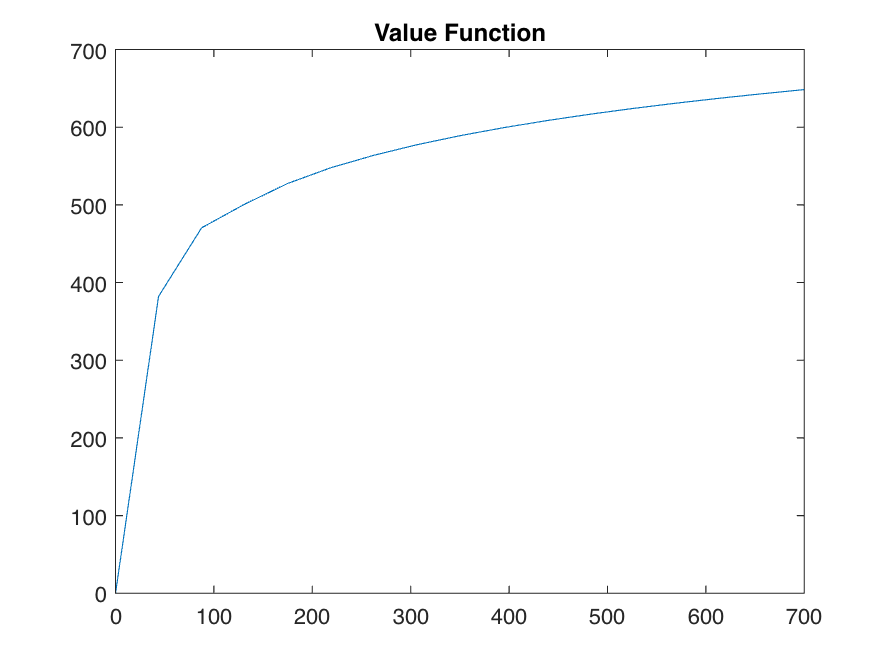


figure(1)
plot(m,V)
title('Value Function')

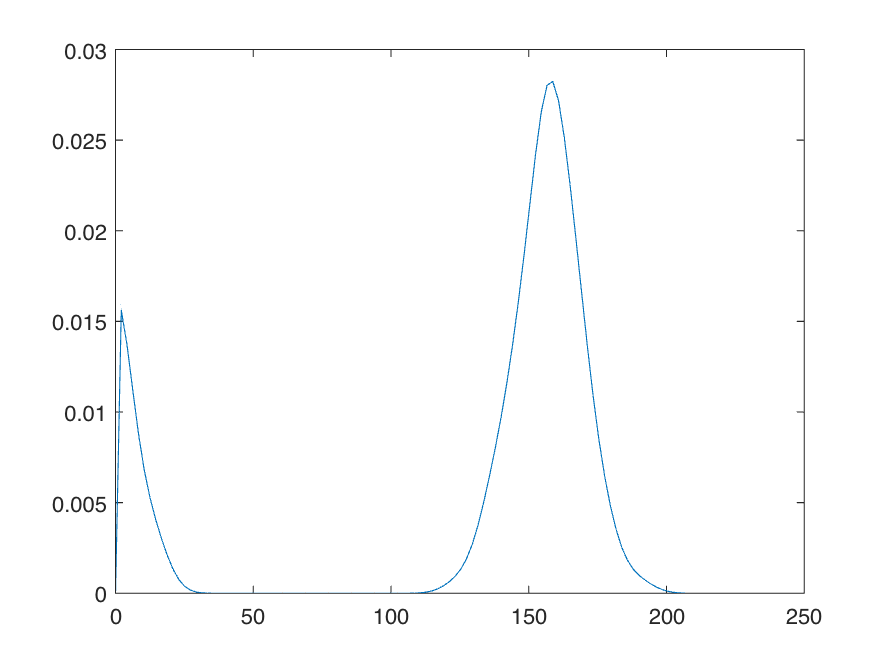


for i=1:N
    if Distribution(1,i)==0;
        Distribution(1,i)=0.001;
    end
end

[f,xi] = ksdensity(Distribution,'Support','positive','BoundaryCorrection','reflection','Bandwidth',std(Distribution)*0.1); 

figure(2)
plot(xi,f)

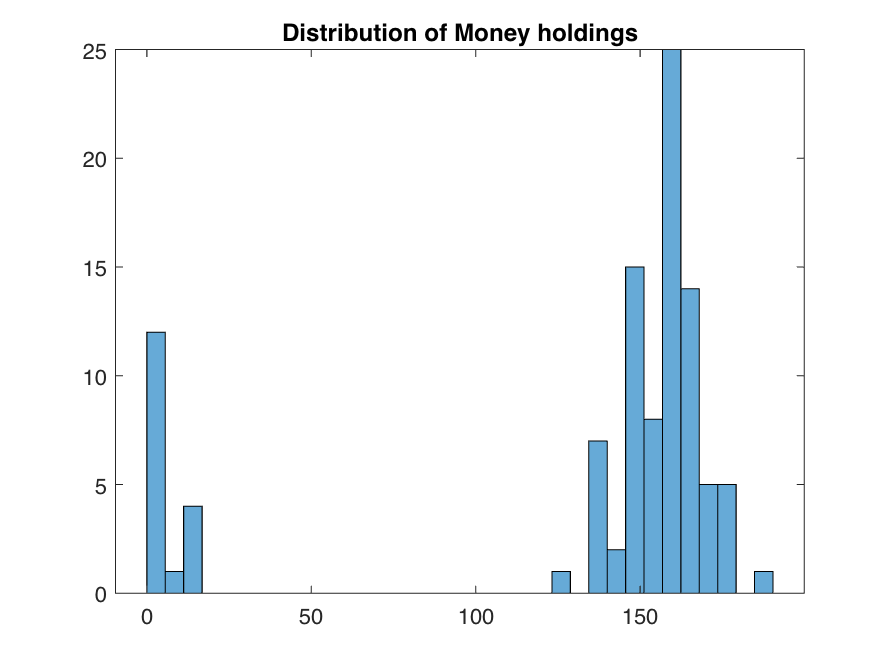



figure(3)
histogram(Distribution,grids*2)
 title('Distribution of Money holdings')

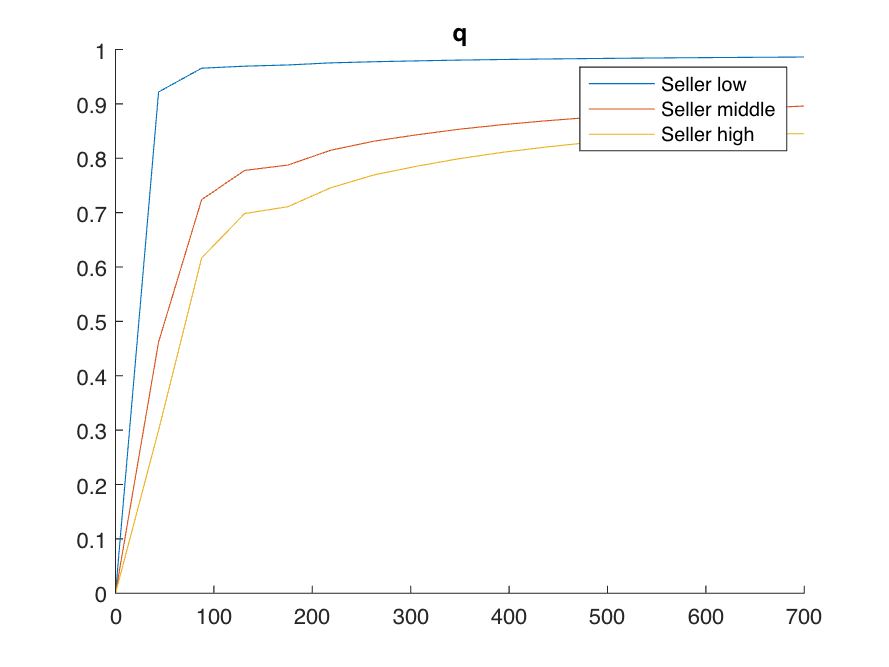


figure(4)
hold on
plot(m,q(:,1))
plot(m,q(:,round(grids/2)))
plot(m,q(:,grids-1))
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('q')

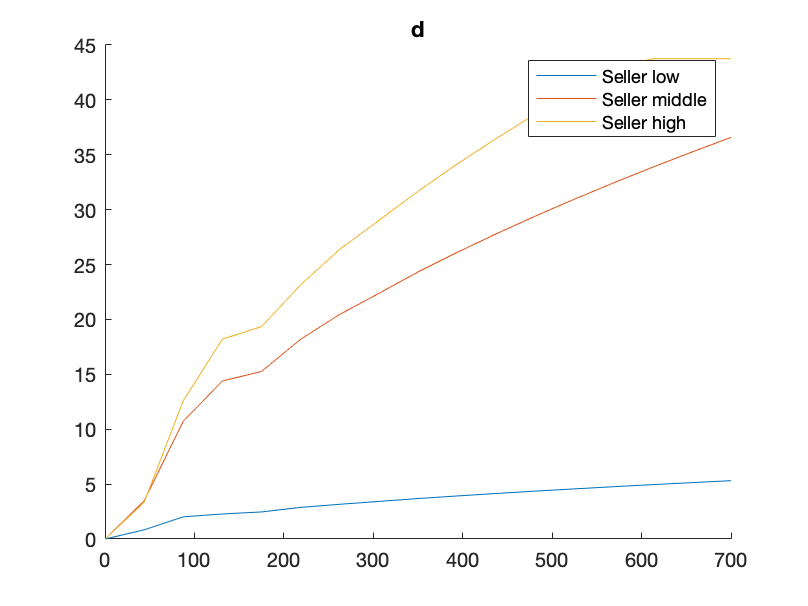



figure(5)
hold on
plot(m,d(:,1))
plot(m,d(:,round(grids/2)))
plot(m,d(:,grids-1))
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('d')

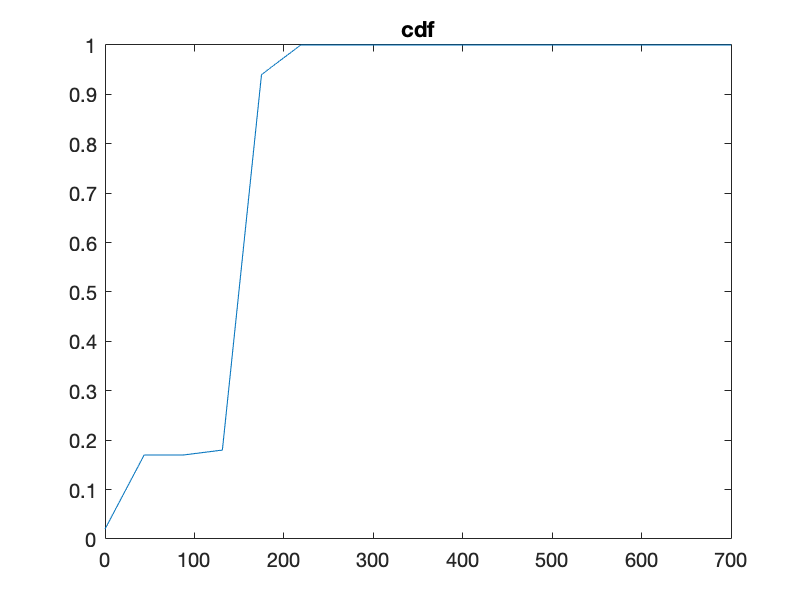


figure (6)
plot(m,cdf)
title('cdf')

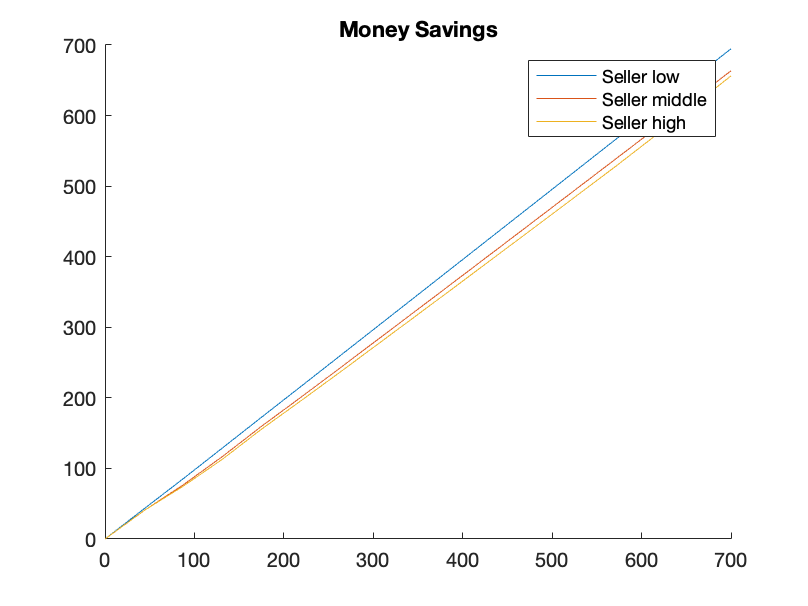


m_savings_1=m'-d(:,1);
m_savings_2=m'-d(:,round(grids/2));
m_savings_3=m'-d(:,grids-1);
figure(7)
hold on
plot(m',m_savings_1)
plot(m',m_savings_2)
plot(m',m_savings_3)
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('Money Savings')


if cdf(grids)==1
    disp('cdf adds up to one')
else 
    disp('cdf does not add up to one')
    cdf(grids)
end

cdf adds up to one


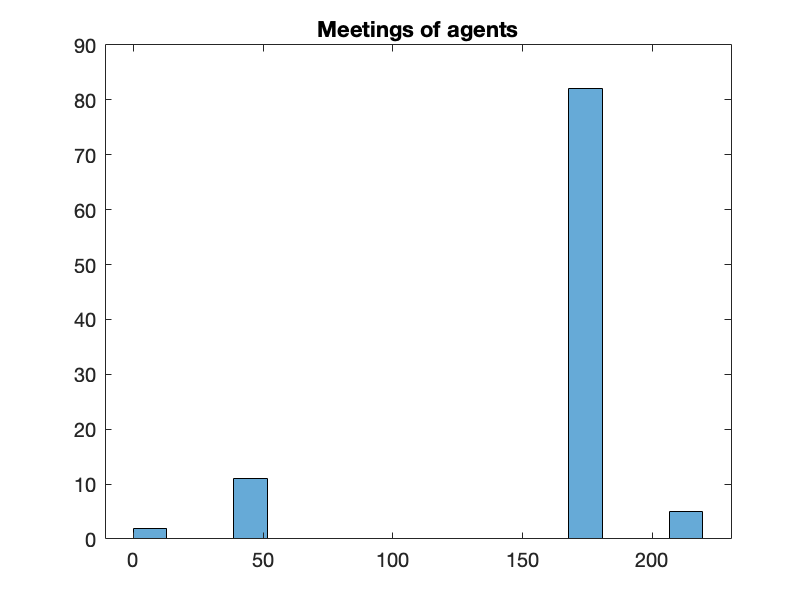

for i=1:N
Meeting(1,i)=m(1,Meeting(1,i));
end

figure (8)
histogram(Meeting,grids)
title('Meetings of agents')


lamdba

lamdba =     0.0200    0.1500         0    0.0100    0.7600    0.0600         0         0         0         0         0         0         0         0         0         0         0



for i=1:grids
V_plot(1,i)=interp1(m,V,m(1,i),'spline',"extrap")-interp1(m,V,m(1,1),'spline',"extrap");
end



index=[1:iterations]

index =      1     2     3     4     5


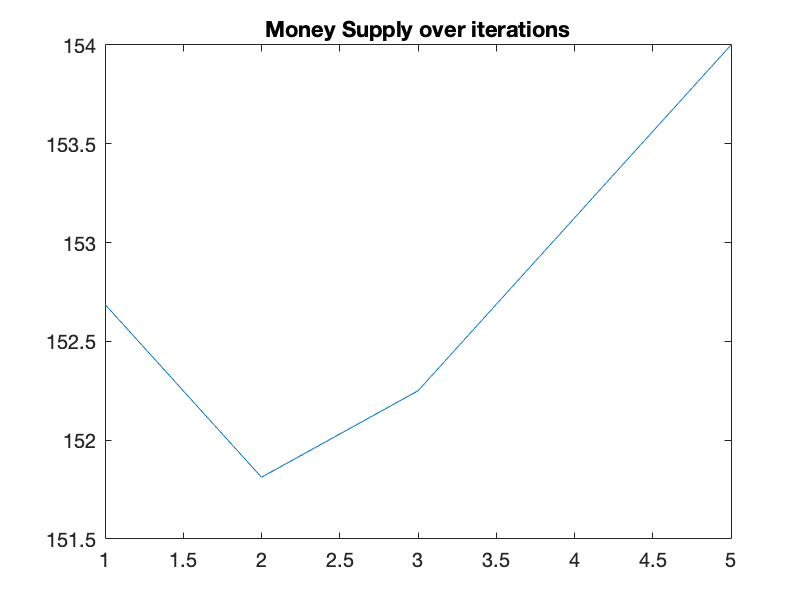

figure(9)
plot(index, M_track_1)
title('Money Supply over iterations')


average_q=sum(sum((lamdba'*lamdba)*q'))

average_q = 14.2041

mean(d./q)

ans =     3.4756    6.2901   14.7335   16.2518   17.8500   20.7109   22.6531   24.5501   26.3751   28.0466   29.6513   31.1767   32.6374   34.0435   35.3963   36.1794         0
